# Tests for debugging purposes

## The equations

## 
$$g(X,Q) = \sum_j \|X-Y_jQ_j\|^2 
\\
\nabla g(X,Q) = 2\bigg(\sum_j(X-Y_jQ_j), Y^\top(YQ-X)\bigg)
\\
\nabla^2 g(X,Q)[U,V] = \nabla g(U,V)$$


## Nonconvex problem

### Data and problem

clear
n=5; % data dimension
k=5; % number of matrices
r=round(n/2); % size of factorization Y of data A
p=r+1; % size of factorization X of barycenter B (r<=p)
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);

### Gradient

The slope should be 2. It appears to be: 2.00001.
If it is far from 2, then directional derivatives might be erroneous.


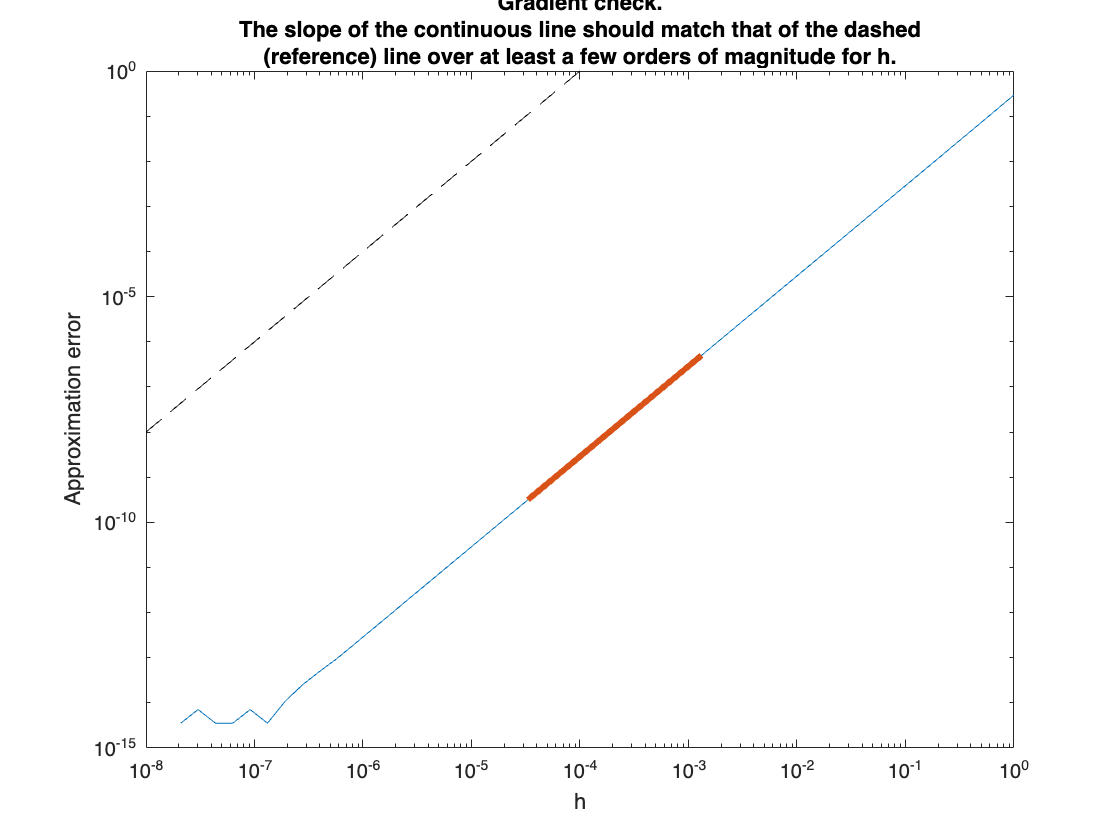

The residual should be 0, or very close. Residual: 1.51208e-15.
If it is far from 0, then the gradient is not in the tangent space.
In certain cases (e.g., hyperbolicfactory), the tangency test is inconclusive.


checkgradient(prob);

### Hessian

checkhessian(prob);

The slope should be 3. It appears to be: 3.00036.
If it is far from 3, then directional derivatives,
the gradient or the Hessian might be erroneous.
Tangency residual should be zero, or very close; residual: 3.04147e-16.
If it is far from 0, then the Hessian is not in the tangent space.
||a*H[d1] + b*H[d2] - H[a*d1+b*d2]|| should be zero, or very close.
	Value: 4.53142e-16 (norm of H[a*d1+b*d2]: 1.66209)
If it is far from 0, then the Hessian is not linear.
<d1, H[d2]> - <H[d1], d2> should be zero, or very close.
	Value: 0.0930706 - 0.0930706 = 6.93889e-17.
If it is far from 0, then the Hessian is not symmetric.


### Optimization

clear
n=32; % data dimension
k=10; % number of matrices
r=round(n/2); % size of factorization Y of data A
p=r+5; % size of factorization X of barycenter B (r<=p)
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);

options.debug=0;
%options.statsfun = @variance_statsfun;
[x, xcost, info, options] = trustregions(prob,[],options);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   +1.2021131773133789e+03   7.491937e+01
acc TR+       1   +9.5636599695781194e+02   6.323164e+01           1           1           1   exceeded trust region
acc TR+       2   +6.0924382370472028e+02   3.912675e+01           1           1           1   exceeded trust region
acc TR+       3   +3.6383467490533013e+02   1.321198e+01           2           2           2   negative curvature
REJ TR-       4   +3.6383467490533013e+02   1.321198e+01           2           2           2   exceeded trust region
acc TR+       5   +3.2458080216144856e+02   1.386396e+01           2           0           2   exceeded trust region
REJ TR-       6   +3.2458080216144856e+02   1.386396e+01           2           2           2   exceeded trust region
acc TR+       7   +2.9989632090418939e+02   8.972258e+00           1           0           2   exceeded trust region
acc           8   +2.

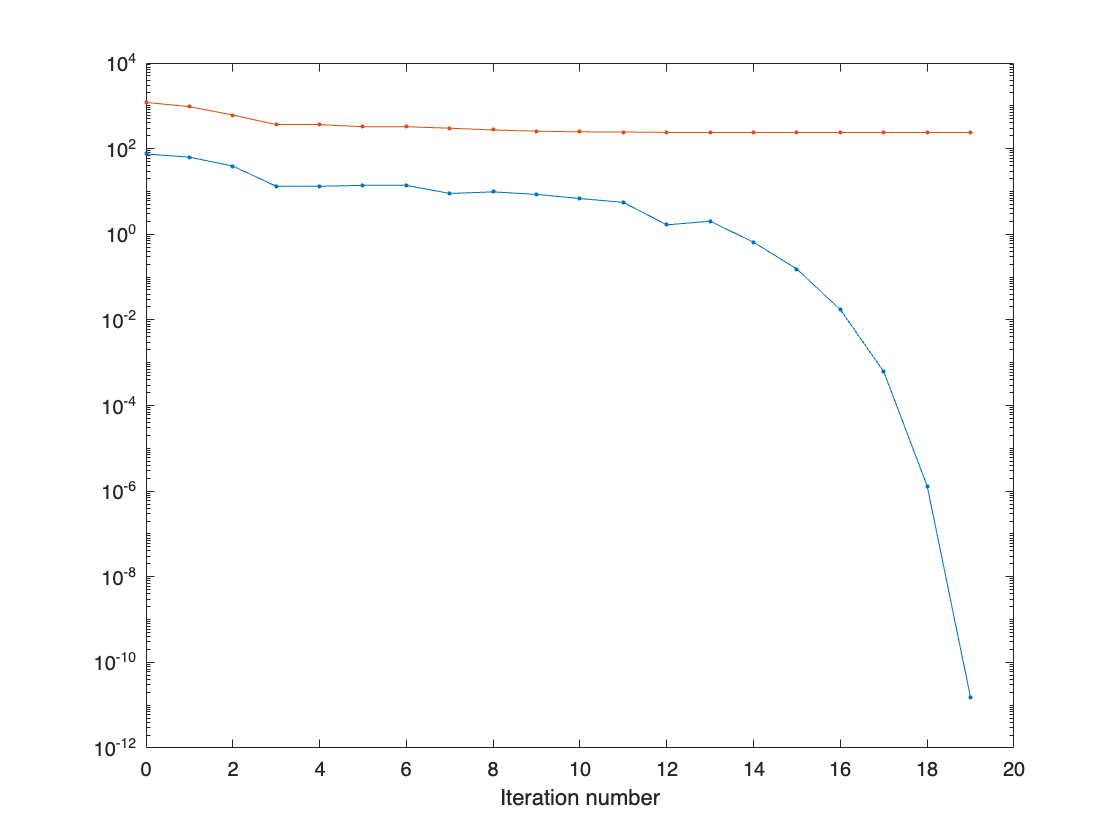

figure;
semilogy([info.iter], [info.gradnorm], '.-',[info.iter],[info.cost],'.-');
xlabel('Iteration number');

## Convex problem

### Data and problem

clear
n=4; % data dimension
k=3; % number of matrices
A = data(n,k,n);
prob2 = convex_problem(A);

### Gradient

checkgradient(prob2);

The slope should be 2. It appears to be: 1.
If it is far from 2, then directional derivatives might be erroneous.


The residual should be 0, or very close. Residual: 0.
If it is far from 0, then the gradient is not in the tangent space.
In certain cases (e.g., hyperbolicfactory), the tangency test is inconclusive.


### Optimization

%options.debug=1;
%options.statsfun = @variance_statsfun;
%[x, xcost, info, options] = trustregions(prob2,[],options);
% figure;
% semilogy([info.iter], [info.gradnorm], '.-',[info.iter],[info.cost],'.-');
% xlabel('Iteration number');